# # CA 3

## Second-Order Dominant

syms sigma wn
equ = 1/(2*sigma*sqrt(1-sigma^2)) == 2;
vpa(solve(equ),2)

$$ans = \left(\begin{array}{c} 0.97\\ 0.26 \end{array}\right)$$

sig = 0.5;
equ2 = wn * sqrt(1-2*sig^2+sqrt(2-4*sig^2 + 4*sig^4)) == 2;
vpa(solve(equ2),2)

$$ans = 1.6$$

syms s
wn = 1.6;
equ3 = s^2 + 2*sig*wn*s + wn^2 == 0;
S = vpa(solve(equ3),2)

$$S = \left(\begin{array}{c} -0.8-1.4\,\mathrm{i}\\ -0.8+1.4\,\mathrm{i} \end{array}\right)$$

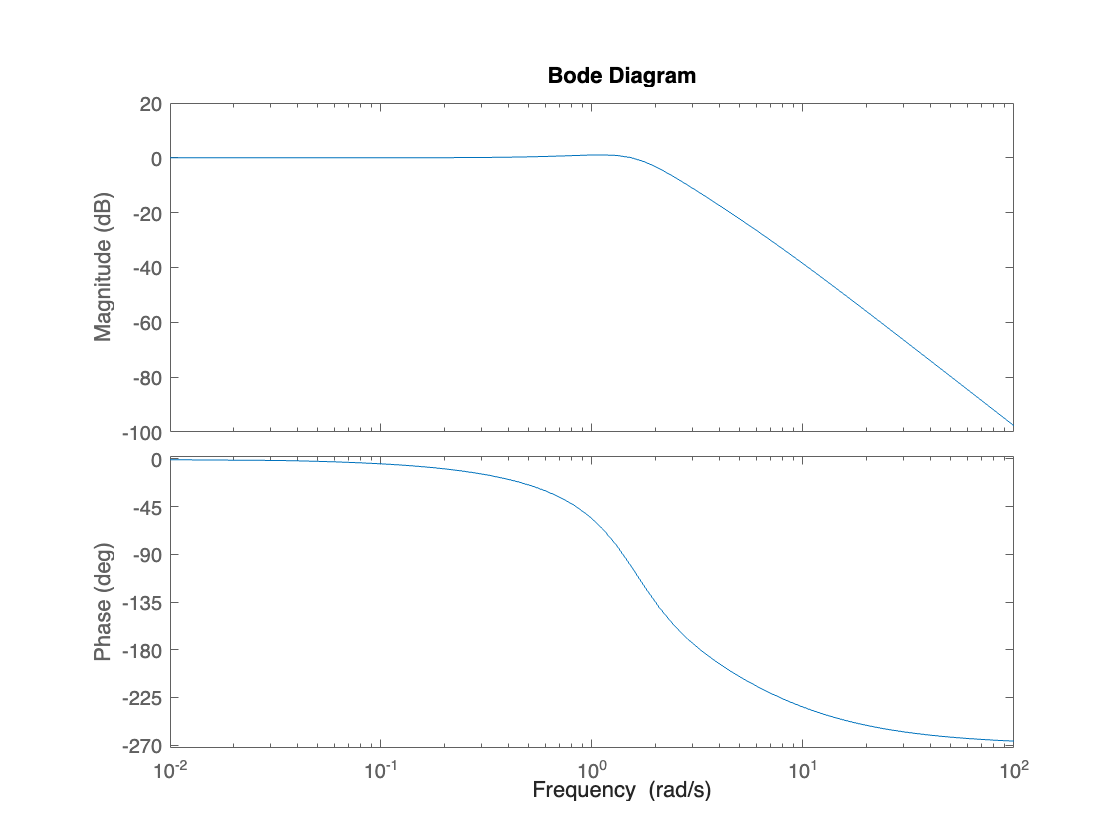

SOD_poles = [-5, -0.8-1.4i, -0.8+1.4i];

F = [0, 1 0; 
    -1.2, -3.71 0; 
    1 0 0]; % Process Matrix
Gu = [0; 1; 0]; % The input matrix for u
Gr = [0; 0; -1]; % The input matrix for r
Gv = [0; 1; 0]; % Disturbance input
H = [1, 0, 0]; % Output Matrix

K_SOD = acker(F, Gu, SOD_poles);

sys_ag_SOD = ss(F - Gu*K_SOD, Gr, H, 0);
bode(sys_ag_SOD)

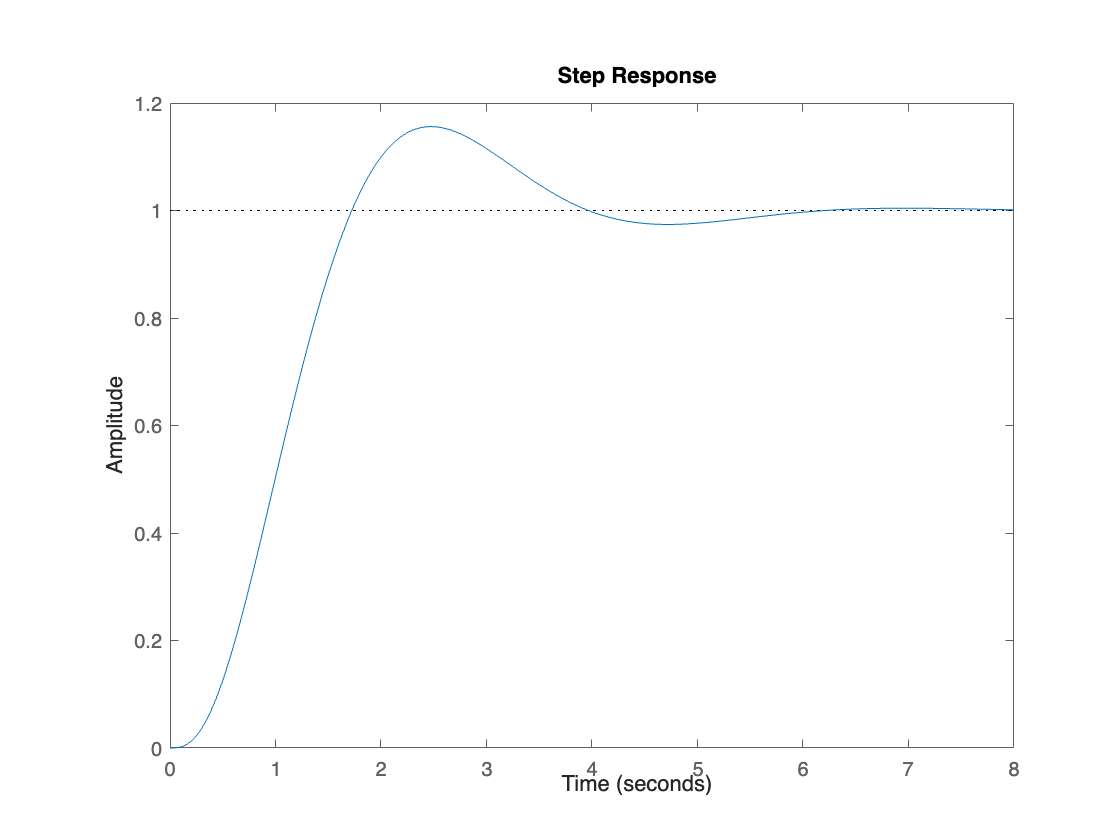

step(sys_ag_SOD)

## ITAE and Ackerman formula calculation

F = [0, 1 0; 
    -1.2, -3.71 0; 
    1 0 0]; % Process Matrix
Gu = [0; 1; 0]; % The input matrix for u
Gr = [0; 0; -1]; % The input matrix for r
Gv = [0; 1; 0]; % Disturbance input
H = [1, 0, 0]; % Output Matrix

syms s
% desired poles: 
poles = 1.5*[-0.7081; -0.5210+1.068*1i; -0.5210-1.068*1i]

poles =   -1.0621 + 0.0000i
  -0.7815 + 1.6020i
  -0.7815 - 1.6020i


poly = expand((s+1.0621)*(s+ 0.7815 + 1.602i)*(s+ 0.7815-1.602i))

$$poly = s^{3}+\frac{26251\,s^{2}}{10000}+\frac{96744171\,s}{20000000}+\frac{26995576257}{8000000000}$$

vpa(poly,4)

$$ans = s^{3}+2.625\,s^{2}+4.837\,s+3.374$$

Sigma = [Gu F*Gu F*F*Gu];
% s^3 + 1.4811s^2 + (1.8193-0.2872i)s+ 0.9006 + 0.2033i
Alpha_F = F^3 + 2.625*F^2 + 4.837*F + 3.374*eye(3)

Alpha_F =     4.6760    7.6623         0
   -9.1948  -23.7513         0
    3.6370   -1.0850    3.3740


K = [0 0 1]*inv(Sigma)*Alpha_F

K =     3.6370   -1.0850    3.3740


% check ackerman formula result
K_ITAE = acker(F, Gu, poles)

K_ITAE =     3.6373   -1.0848    3.3746


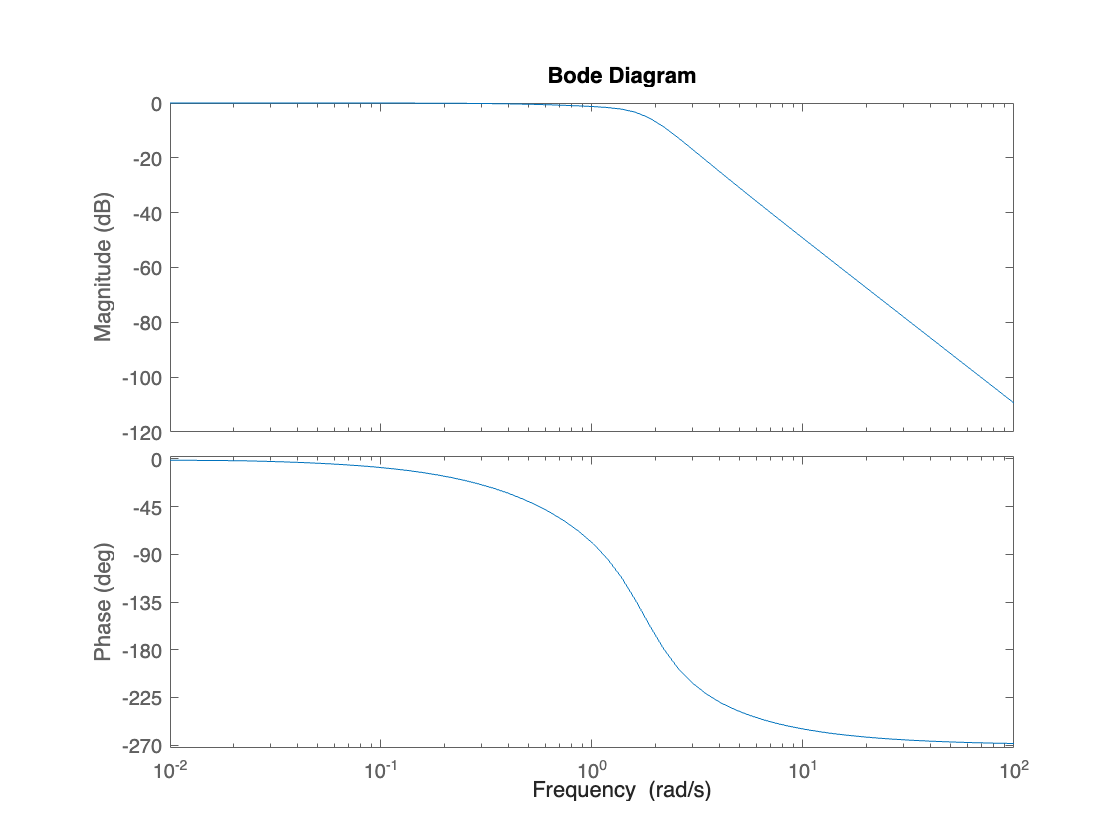

sys_ack = ss(F-Gu * K_ITAE, Gr, H, 0);
% Bode plot and step plot without scaling gain
bode(sys_ack)

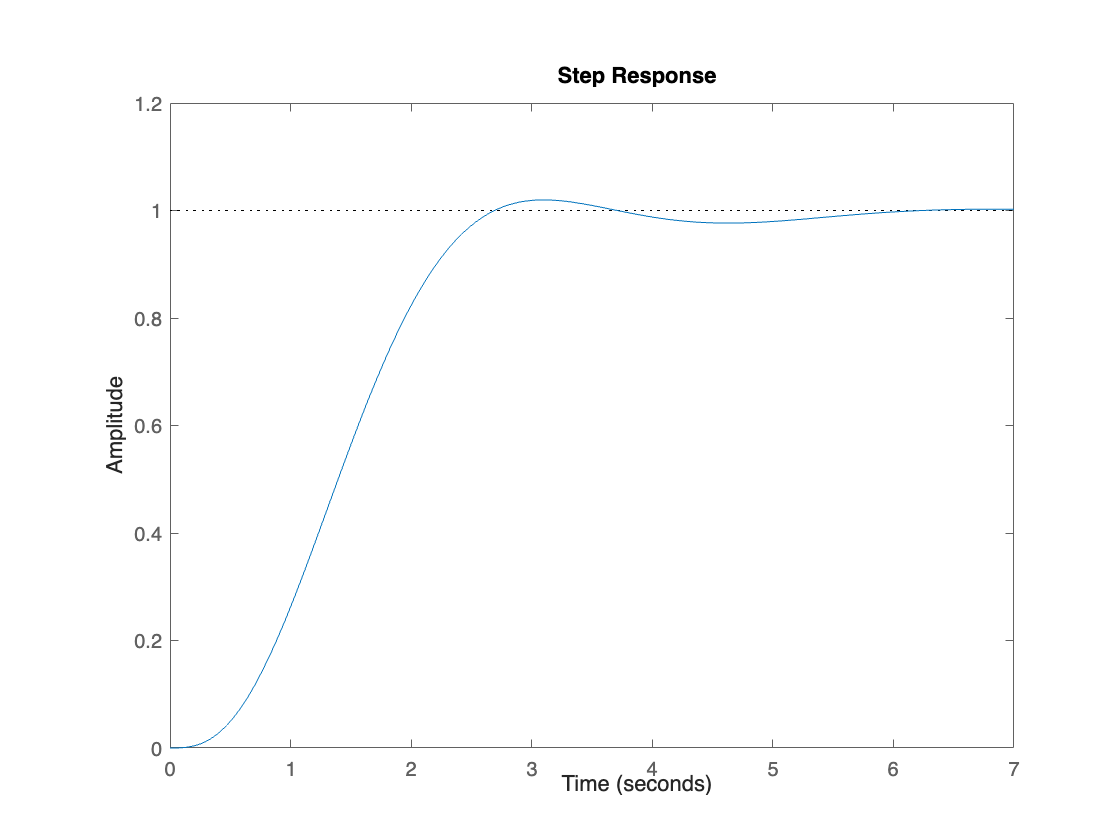

step(sys_ack)

sys_ack

sys_ack =
 
  A = 
           x1      x2      x3
   x1       0       1       0
   x2  -4.837  -2.625  -3.375
   x3       1       0       0
 
  B = 
       u1
   x1   0
   x2   0
   x3  -1
 
  C = 
       x1  x2  x3
   y1   1   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



[num,den] = ss2tf(sys_ack.A, sys_ack.B, sys_ack.C, sys_ack.D)

num =          0         0         0    3.3746


den =     1.0000    2.6252    4.8373    3.3746


% scaling gain
scaling_gain  = 16.1506

scaling_gain = 16.1506

sys_ack = scaling_gain*sys_ack

sys_ack =
 
  A = 
           x1      x2      x3
   x1       0       1       0
   x2  -4.837  -2.625  -3.375
   x3       1       0       0
 
  B = 
       u1
   x1   0
   x2   0
   x3  -1
 
  C = 
          x1     x2     x3
   y1  16.15      0      0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


bode(sys_ack)

step(sys_ack)

## Bessel approach

BesselPoles = 2.5 * [-0.9420;-0.7455+0.7112*1i;-0.7455-0.7112*1i];
K_Bessel = acker(F, Gu, BesselPoles);
sys_ag_Bessel = ss(F - Gu*K_Bessel, Gr, H, 0);
bode(sys_ag_Bessel)
step(sys_ag_Bessel)

## LQR approach

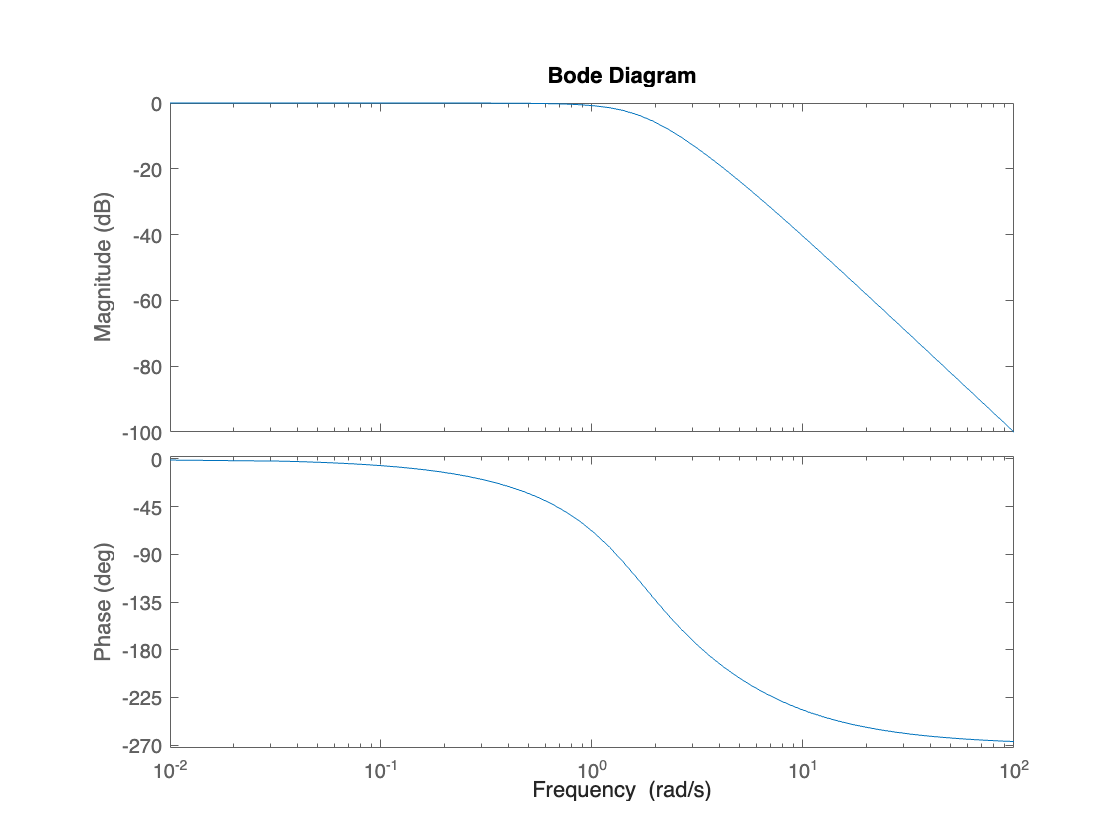

Q_LQR = [5,  0,  0;
         0,  1,  0;
         0,  0, 100];
R_LQR = 1;
[K_LQR,~,~] = lqr(F, Gu, Q_LQR, R_LQR);
sys_ag_LQR = ss(F -Gu * K_LQR, Gr, H, 0);

% Bode plot and step plot without scaling gain
bode(sys_ag_LQR)

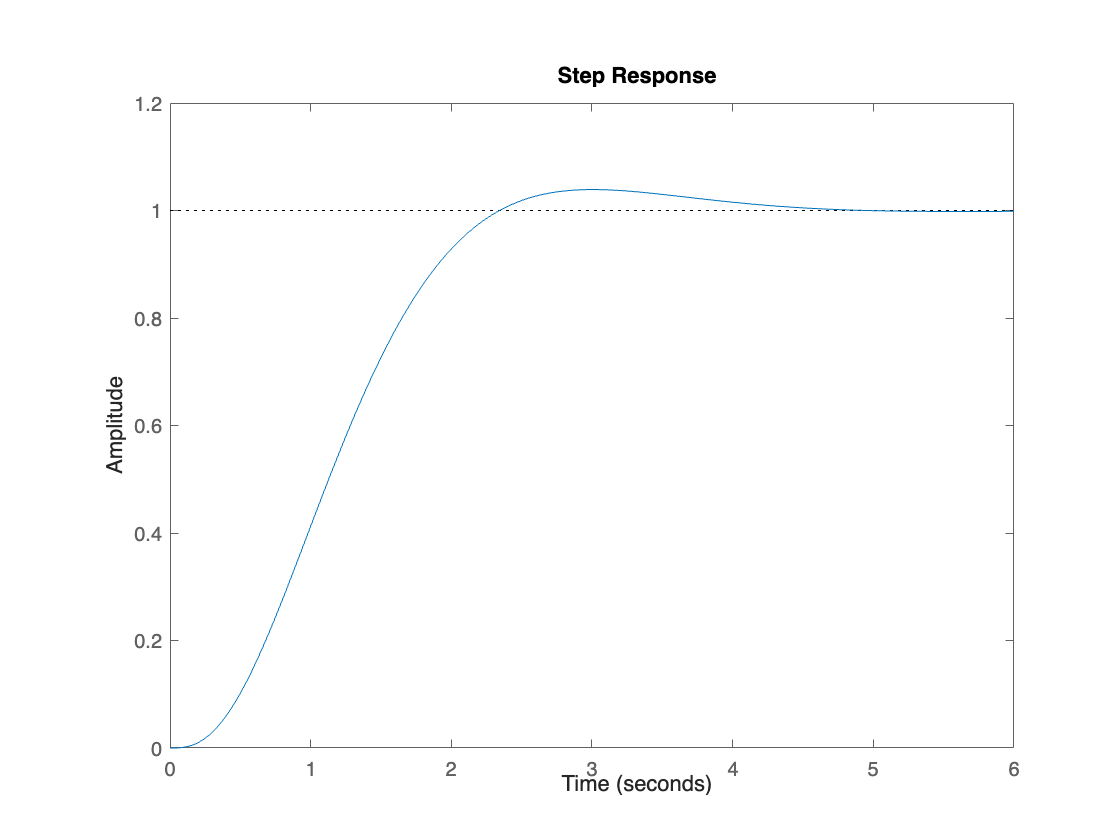

step(sys_ag_LQR)

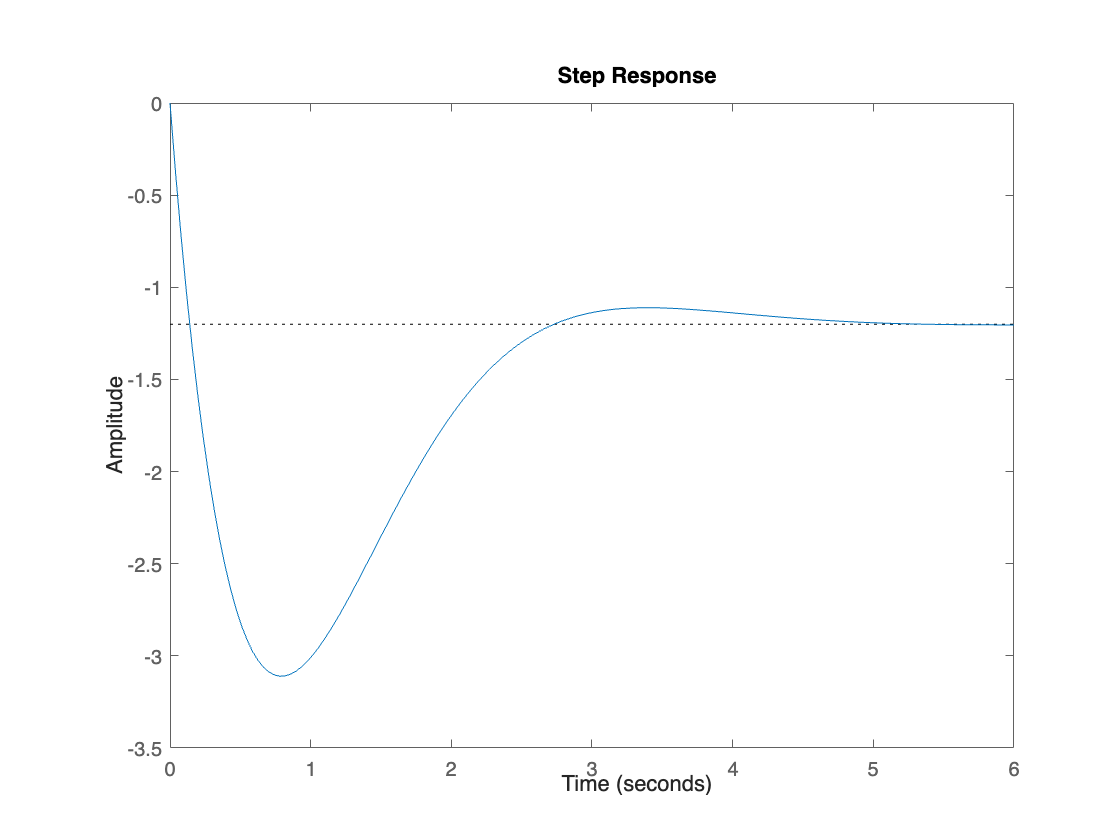

% Output response to control signal
sys_ag_LQR_ctr = ss(F -Gu * K_LQR, Gr, K_LQR, 0);
% Bode plot and step plot without scaling gain
step(sys_ag_LQR_ctr)

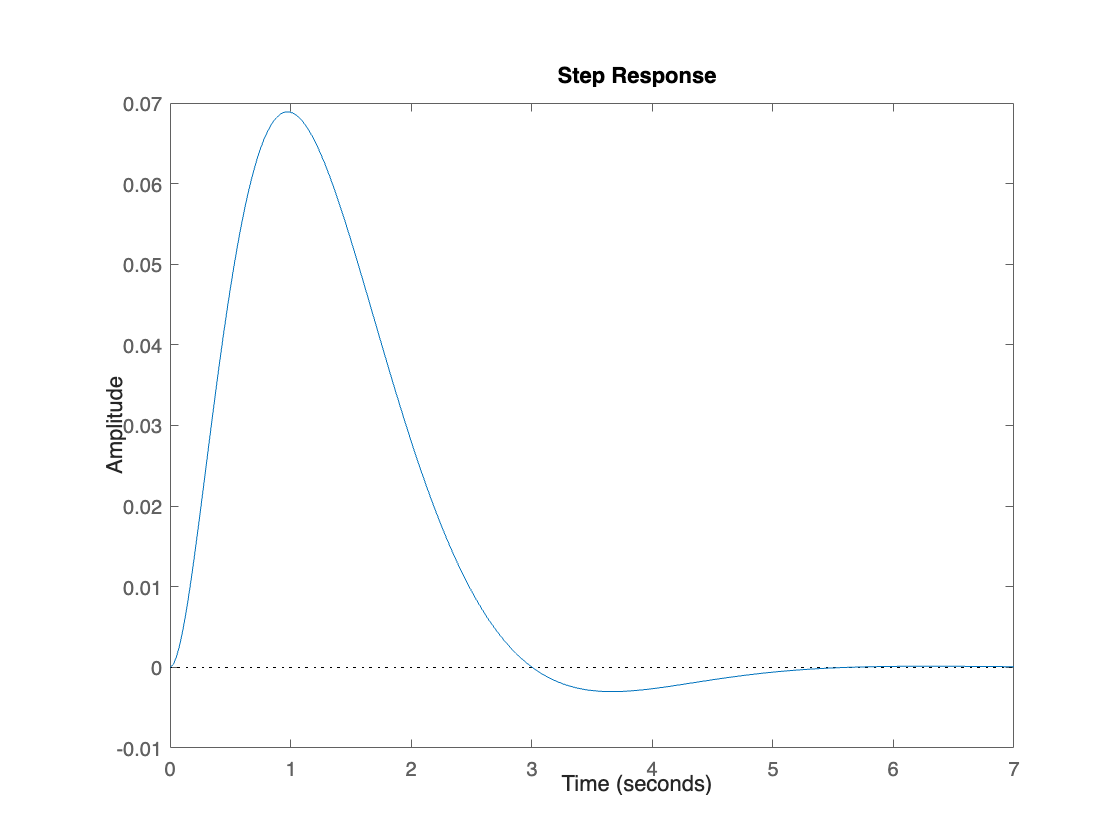

% Output response to disturebance
sys_ag_LQR_ctr = ss(F-Gu * K_LQR, Gv, H, 0);
% Bode plot and step plot without scaling gain
step(sys_ag_LQR_ctr)

## Disturbance analysis

% SOD Output response to disturebance
sys_ag_SOD_dis = ss(F-Gu * K_SOD, Gv, H, 0);
% Bode plot and step plot without scaling gain
step(sys_ag_SOD_dis)
title('SOD disturbance response')

% ITAE Output response to disturebance
sys_ag_ITAE_dis = ss(F-Gu * K_ITAE, Gv, H, 0);
% Bode plot and step plot without scaling gain
step(sys_ag_ITAE_dis)
title('ITAE disturbance response')

% Bessel Output response to disturebance
sys_ag_Bessel_dis = ss(F-Gu * K_Bessel, Gv, H, 0);
% Bode plot and step plot without scaling gain
step(sys_ag_Bessel_dis)
title('Bessel disturbance response')

% LQR Output response to disturebance
sys_ag_LQR_ctr = ss(F-Gu * K_LQR, Gv, H, 0);
% Bode plot and step plot without scaling gain
step(sys_ag_LQR_ctr)
title('LQR disturbance response')


%% Response to Control signal 
% SOD Output response to control signal
sys_ag_SOD_ctr = ss(F -Gu * K_SOD, Gr, K_LQR, 0);
% Bode plot and step plot without scaling gain
step(sys_ag_SOD_ctr) 
title('SOD control signal response')

% ITAE Output response to control signal
sys_ag_ITAE_ctr = ss(F -Gu * K_ITAE, Gr, K_LQR, 0);
% Bode plot and step plot without scaling gain
step(sys_ag_ITAE_ctr) 
title('ITAE control signal response')

% Bessel Output response to control signal
sys_ag_Bessel_ctr = ss(F -Gu * K_Bessel, Gr, K_LQR, 0);
% Bode plot and step plot without scaling gain
step(sys_ag_Bessel_ctr) 
title('Bessel control signal response')

% LQR Output response to control signal
sys_ag_LQR_ctr = ss(F -Gu * K_LQR, Gr, K_LQR, 0);
% Bode plot and step plot without scaling gain
step(sys_ag_LQR_ctr) 
title('LQR control signal response')



## Transfer function

% SOD
[num, den] = ss2tf(F-Gu * K_SOD, Gr, H, 0);
sys_tf_SOD = tf(num,den)

sys_tf_SOD =
 
              13
  ---------------------------
  s^3 + 6.6 s^2 + 10.6 s + 13
 
Continuous-time transfer function.
Model Properties


%
[num, den] = ss2tf(F-Gu * K_ITAE, Gr, H, 0);
sys_tf_ITAE = tf(num,den)

sys_tf_ITAE =
 
                3.375
  ---------------------------------
  s^3 + 2.625 s^2 + 4.837 s + 3.375
 
Continuous-time transfer function.
Model Properties


%
[num, den] = ss2tf(F-Gu * K_Bessel, Gr, H, 0);
sys_tf_Bessel = tf(num,den)

sys_tf_Bessel =
 
                15.63
  ---------------------------------
  s^3 + 6.082 s^2 + 15.41 s + 15.63
 
Continuous-time transfer function.
Model Properties


%
[num, den] = ss2tf(F-Gu * K_LQR, Gr, H, 0);
sys_tf_LQR = tf(num,den)

sys_tf_LQR =
 
                10
  ------------------------------
  s^3 + 5.886 s^2 + 11.14 s + 10
 
Continuous-time transfer function.
Model Properties
